test

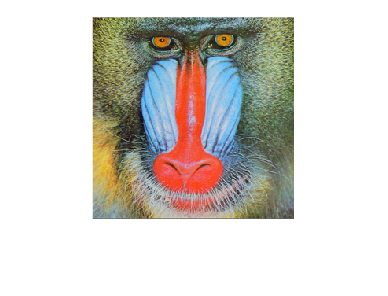

addpath("figs/") ; 
addpath("QCLAB/") ; 
addpath("siable") ; 
Image_baboon = imread("baboon.png") ; 
Image_baboon = imresize(Image_baboon, [256, 256]) ; 
imshow(Image_baboon) ; 


n = log2( size(Image_baboon, 1) ) ; 

fprintf("256 * 256 * 3 pixels") ; 

256 * 256 * 3 pixels

tic ;  
rank = pow2(n) ; 
[New_image_full, info_full] = Image_block_encoding(Image_baboon, rank, n ) ;
New_image_full = uint8( New_image_full ) ; 
imshow(New_image_full)
info_full.nCNOT 
rank 
pnsr = calculate_psnr(double(Image_baboon), double(New_image_full)) 
toc ; 

tic ;  
rank = 5 ; 
[New_image_5, info_5] = Image_block_encoding(Image_baboon, rank, n ) ;
New_image_5 = uint8( New_image_5 ) ;
imshow(New_image_5)
info_5.nCNOT 
rank 
pnsr = calculate_psnr(double(Image_baboon), double(New_image_5)) 
toc ; 

tic ;  
rank = 10 ; 
[New_image_10, info_10] = Image_block_encoding(Image_baboon, rank, n ) ;
New_image_10 = uint8( New_image_10 ) ; 
imshow(New_image_10) 
info_10.nCNOT 
rank 
pnsr = calculate_psnr(double(Image_baboon), double(New_image_10)) 
toc ; 

tic ;  
rank = 30 ; 
[New_image_30, info_30] = Image_block_encoding(Image_baboon, rank, n ) ;
New_image_30 = uint8( New_image_30 ) ; 
imshow(New_image_30) 
info_30.nCNOT 
rank 
pnsr = calculate_psnr(double(Image_baboon), double(New_image_30)) 
toc ; 


New_image_30 = uint8( New_image_30 ) ; 
imshow(New_image_30) 
info_30.nCNOT 
rank 
pnsr = calculate_psnr(double(Image_baboon), double(New_image_30)) 
toc 

function calculate_psnr(original_img, processed_img) 

function psnr_value = calculate_psnr(original_img, processed_img)
% Calculate the Peak Signal-to-Noise Ratio (PSNR) between two images
% Inputs:
%   original_img - Original image (grayscale image, matrix form)
%   processed_img - Processed image (grayscale image, matrix form)
% Outputs:
%   psnr_value - Peak Signal-to-Noise Ratio (dB)

% Ensure input images are double precision floating point
original_img = double(original_img);
processed_img = double(processed_img);

% Check if image sizes are consistent
if ~isequal(size(original_img), size(processed_img))
    error('Input images must have the same size');
end

% Calculate Mean Squared Error (MSE)
mse = mean((original_img(:) - processed_img(:)).^2);

% If MSE is 0, PSNR is defined as infinity
if mse == 0
    psnr_value = Inf;
    return;
end

% Get the maximum pixel value of the image (typically 255 for grayscale images)
max_pixel_value = 255;

% Calculate PSNR
psnr_value = 10 * log10((max_pixel_value^2) / mse);

end


function New_image = Image_threshold(Image, rank) 

    img1 = double( Image(:,:,1) ) ; 
    img2 = double( Image(:,:,2) ) ; 
    img3 = double( Image(:,:,3) ) ; 
    
    [U1,S1,V1] = svd(img1) ; 
    [U2,S2,V2] = svd(img2) ; 
    [U3,S3,V3] = svd(img3) ; 

    S1 = diag(S1) ; 
    S1 = S1(1:rank) ; 
    if rank ~= min( size(Image) ) 
        S1(size(Image,1)) = 0 ; 
    end 

    S2 = diag(S2) ; 
    S2 = S2(1:rank) ; 
    if rank ~= min( size(Image) ) 
        S2(size(Image,1)) = 0 ; 
    end 

    S3 = diag(S3) ; 
    S3 = S3(1:rank) ; 
    if rank ~= min( size(Image) ) 
        S3(size(Image,1)) = 0 ; 
    end 

    img1 = U1 * diag(S1) * V1' ;
    img2 = U2 * diag(S2) * V2' ; 
    img3 = U3 * diag(S3) * V3' ;

    New_image = cat(3, img1, img2, img3 ) ; 
end

function [New_image, info] = Image_block_encoding(Image, rank, n) 

    img1 = double( Image(:,:,1) ) ; 
    img2 = double( Image(:,:,2) ) ; 
    img3 = double( Image(:,:,3) ) ; 
    assert( size(img1,1) == size(img1,2) ) ; 

    logging = true ; 
    offset = 0 ; 

    if rank == min(size(img1))  % full-rank
    
        [circuit1, subnormalization1, info1] = siable( img1, logging, offset ) ; 
        [circuit2, subnormalization2, info2] = siable( img2, logging, offset ) ; 
        [circuit3, subnormalization3, info3] = siable( img3, logging, offset ) ; 

    else % low-rank 
        
        [circuit1, subnormalization1, info1] = siable_low_rank( img1, rank, logging, offset ) ; 
        [circuit2, subnormalization2, info2] = siable_low_rank( img2, rank, logging, offset ) ; 
        [circuit3, subnormalization3, info3] = siable_low_rank( img3, rank, logging, offset ) ; 

    end 

    M1 = circuit1.matrix .* subnormalization1 ; 
    M2 = circuit2.matrix .* subnormalization2 ; 
    M3 = circuit3.matrix .* subnormalization3 ; 
    info = struct() ; 
    info.subnormalization1 = subnormalization1 ; 
    info.subnormalization2 = subnormalization2 ; 
    info.subnormalization3 = subnormalization3 ; 
    info.nCNOT1 = info1.nCNOT ; 
    info.nCNOT2 = info2.nCNOT ; 
    info.nCNOT3 = info3.nCNOT ; 
    info.nCNOT = info.nCNOT1 + info.nCNOT2 + info.nCNOT3 ; 

        
    New_image = cat(3, M1(1:pow2(n), 1:pow2(n)), M2(1:pow2(n), 1:pow2(n)), M3(1:pow2(n), 1:pow2(n)) ) ; 

end

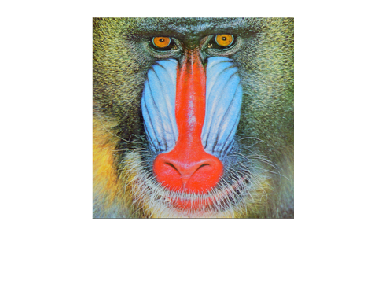

figure ; 

rank = 200 ; 
Image_baboon_200 = uint8(Image_threshold(Image_baboon, 200) ) ;
imshow( Image_baboon_200 ) ; 

rank

rank = 200

psnr_value = calculate_psnr(Image_baboon, Image_baboon_200) 

psnr_value = 48.9613

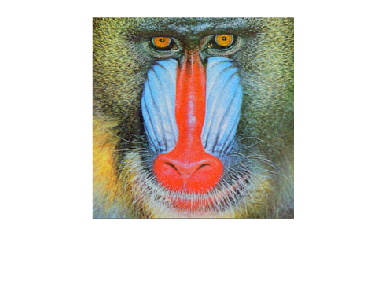


rank = 100 ; 
Image_baboon_100 = uint8(Image_threshold(Image_baboon, 100) ) ;
imshow( Image_baboon_100 ) ; 

rank

rank = 100

psnr_value = calculate_psnr(Image_baboon, Image_baboon_100)

psnr_value = 32.9255

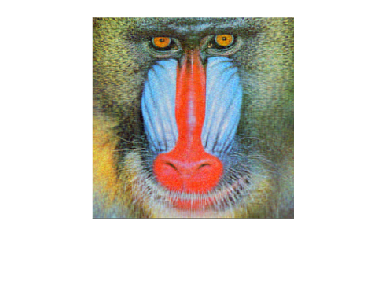


rank = 45 ; 
Image_baboon_45 = uint8(Image_threshold(Image_baboon, 45) ) ;
imshow( Image_baboon_45 ) ; 

rank

rank = 45

psnr_value = calculate_psnr(Image_baboon, Image_baboon_45)

psnr_value = 26.4864

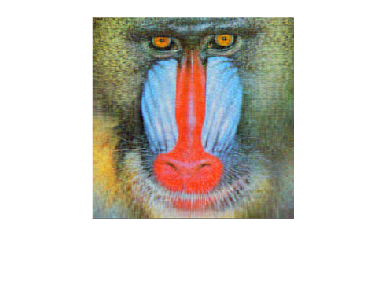


rank = 30 ; 
Image_baboon_30 = uint8(Image_threshold(Image_baboon, 30) ) ;
imshow( Image_baboon_30 ) ; 

rank

rank = 30

psnr_value = calculate_psnr(Image_baboon, Image_baboon_30)

psnr_value = 24.7218

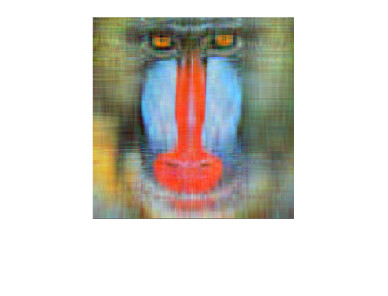


rank = 10 ; 
Image_baboon_10 = uint8(Image_threshold(Image_baboon, 10) ) ; 
imshow( Image_baboon_10 ) ; 

rank

rank = 10

psnr_value = calculate_psnr(Image_baboon, Image_baboon_10)

psnr_value = 21.8039

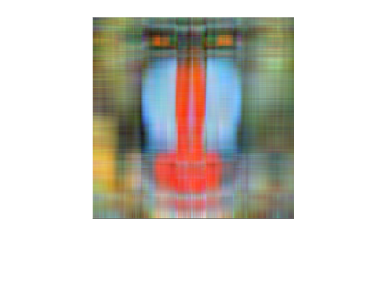


rank = 5 ;
Image_baboon_5 = uint8(Image_threshold(Image_baboon, 5) ) ; 
imshow( Image_baboon_5 ) ; 

rank 

rank = 5

psnr_value = calculate_psnr(Image_baboon, Image_baboon_5)

psnr_value = 20.3212